# Post-Run Data Analysis: Perfusitech Ex-R

After running app_conversion, take csv from liver computer.

Run this code inside "YYMMDD Data" folder 

clearvars
%Make variables from python-generated CSVs
HA_gas = readtable('Arterial Gas Mixer_GasMixerPoints.csv');
HA_pump = readtable('Arterial PuraLev_RawPoints.csv');
CDI = readtable('CDI_CDIPoints.csv');
DialysisIn = readtable('Dialysate Inflow Pump_RawPoints.csv');
DialysisOut = readtable('Dialysate Outflow Pump_RawPoints.csv');
DialysisBlood = readtable('Dialysis Blood Pump_RawPoints.csv');
HA_flow = readtable('Hepatic Artery Flow_MovAvg_11pt.csv');
HA_pressure = readtable('Hepatic Artery Pressure_MovAvg_11pt.csv');
PV_flow = readtable('Portal Vein Flow_MovAvg_11pt.csv');
PV_pressure = readtable('Portal Vein Pressure_MovAvg_11pt.csv');
PV_gas = readtable("Venous Gas Mixer_GasMixerPoints.csv");
PV_pump = readtable('Venous PuraLev_RawPoints.csv');

%ignoring drugs for now

% Establishing liver start time from HA nova data
HAdataRaw = readtable("HepaticArteryLabs.csv","VariableNamingRule","preserve");

Dates = table2array(HAdataRaw(:,1));
TimeSinceStart = table2array(HAdataRaw(:,2));
LiverStartMask = TimeSinceStart == 0;
LiverStart = Dates(LiverStartMask);
liver_start_time = 0;
LiverStart

LiverStart = datetime
   07/09/2024 14:45



% Experimental Annotations
ExperimentalConclusions = readtable("ExperimentalOverview.csv", "VariableNamingRule","preserve")

ExperimentalConclusions = 104×4 table
           Var1            Var2                                                                                      Var3                                                                                              Var4        
    ___________________    ____    _________________________________________________________________________________________________________________________________________________________________________    ___________________

                    NaT     NaN    {'Start'                                                                                                                                                                }    07/09/2024 02:45 PM
                    NaT     NaN    {'Death'                                                                                                  

ExperimentalConclusionsRaw = table2cell(ExperimentalConclusions);
ECTimeRaw = ExperimentalConclusionsRaw(9:end,2);
ECTimeMask = [];
for i = 1:numel(ECTimeRaw)
    temp = isnumeric(ECTimeRaw{i}) && ECTimeRaw{i} >= 0;
    ECTimeMask = [ECTimeMask temp];
end
ECTimeMask = logical(ECTimeMask);
ECTime = ECTimeRaw(ECTimeMask);

AnnotationsRaw = ExperimentalConclusionsRaw(9:end,3);
AnnotationsRaw = AnnotationsRaw(ECTimeMask);
AnnotationsMask = [];
for i = 1:numel(AnnotationsRaw)
    Temp = startsWith(AnnotationsRaw(i),'*');
    AnnotationsMask = [AnnotationsMask Temp];
end
AnnotationsMask = logical(AnnotationsMask);

AnnotationsTime = cell2mat(ECTime(AnnotationsMask));
Annotations = AnnotationsRaw(AnnotationsMask);
for i = 1:length(Annotations)
    temp = Annotations{i};
    temp = temp(2:end);
    Annotations(i) = {temp};
end
AnnotationsLength = 1:length(Annotations);
AlphabetFull = cellstr(char('a':'z')');
Alphabet = AlphabetFull(AnnotationsLength);

Time = array2table(AnnotationsTime);
Event = cell2table(Alphabet);
Descriptions = cell2table(Annotations);

#### Notable Events

disp(table(Event,Time,Descriptions));

% make time into duration for all variables
%HA GAS
HA_gas_time_raw = table2array(HA_gas(:,1));
HA_gas_time = hours(HA_gas_time_raw - LiverStart);

%PV GAS
PV_gas_time_raw = table2array(PV_gas(:,1));
PV_gas_time = hours(PV_gas_time_raw - LiverStart);

%HA FLOW
HA_flow_time_raw = table2array(HA_flow(:,"Var1"));
HA_flow_time = hours(HA_flow_time_raw - LiverStart)-3.79;

%PV FLOW
PV_flow_time_raw = table2array(PV_flow(:,"Var1"));
PV_flow_time = hours(PV_flow_time_raw - LiverStart)-3.79;

%HA PUMP
HA_pump_time_raw = table2array(HA_pump(:,"Var1"));
HA_pump_time = hours(HA_pump_time_raw - LiverStart);

%PV PUMP
PV_pump_time_raw = table2array(PV_pump(:,"Var1"));
PV_pump_time = hours(PV_pump_time_raw - LiverStart);

%HA PRESURE
HA_pressure_time_raw = table2array(HA_pressure(:,"Var1"));
HA_pressure_time = hours(HA_pressure_time_raw - LiverStart)-3.79;

%PV PRESSURE
PV_pressure_time_raw = table2array(PV_pressure(:,"Var1"));
PV_pressure_time = hours(PV_pressure_time_raw - LiverStart)-3.79;

%CDI
CDI_time_raw = table2array(CDI(:,1));
CDI_time = hours(CDI_time_raw - LiverStart);

% turn each variable from table to array
HAgas = table2array(HA_gas(:,3));
%%%%%%%%%%%%%%%%%%%%% gas rate needs to be multiplied by Var4 and Var5 as a percent
PVgas = table2array(PV_gas(:,3));
%%%%%%%%%%%%%%%%%%%%%
PVpump = table2array(PV_pump(:,2));
HApump = table2array(HA_pump(:,2));
PVflow = table2array(PV_flow(:,2));
HAflow = table2array(HA_flow(:,2));
HApressure = table2array(HA_pressure(:,2));
PVpressure = table2array(PV_pressure(:,2));
hapH = table2array(CDI(:,2));
pvpH = table2array(CDI(:,11));
haPCO2 = table2array(CDI(:,3));
pvPCO2 = table2array(CDI(:,12));
haPO2 = table2array(CDI(:,4));
pvPO2 = table2array(CDI(:,13));
haSO2 = table2array(CDI(:,6));
pvSO2 = table2array(CDI(:,15));
k = table2array(CDI(:,9));
hct = table2array(CDI(:,18));
hgb = table2array(CDI(:,19));

%need to turn this data to actual flow 

%%%%%%%%%%%%%%%%% Parsing Variables to Smooth Data
FlowParse = floor(length(HAflow)/100); %use FlowParse for HA Pump data to get good sinusoids
GasParse = floor(length(HAgas)/10);
CO2Parse = floor(length(haPCO2)/10);
PressureParse = floor(length(HApressure)/100);
%%%%%%%%%%%%%%%%%

**Blood Flow Rate**

Important notes on this run: full sized pig liver, so targeted 1000-1500 in PV, 200-300 in HA; PV pump died a few times before liver went on (a cable was loose attaching it to the portable power supply). PV drop to zero was when we took out the PV oxygenator and had to make sure the air gap from doing this was directed into the parallel PV branch and not the liver (so we clamped off the liver branch for a minute)

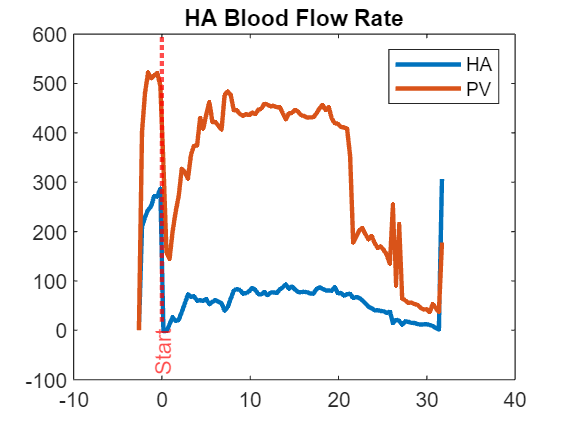

clf

plot(HA_flow_time(1:FlowParse:end), HAflow(1:FlowParse:end), "LineWidth",2)
title("HA Blood Flow Rate")
hold on
plot(PV_flow_time(1:FlowParse:end), PVflow(1:FlowParse:end), "LineWidth",2)
xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
legend("HA","PV")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

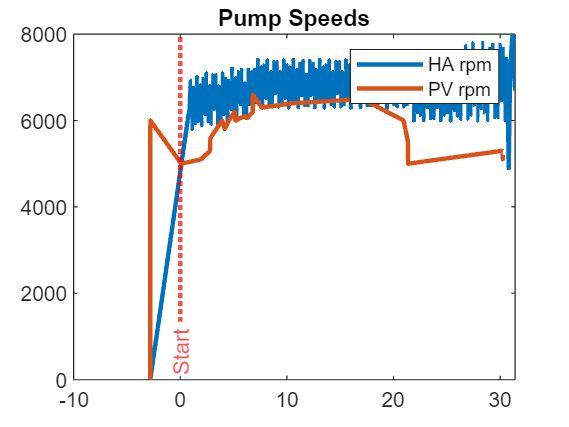


clf
plot(HA_pump_time(1:FlowParse:end), HApump(1:FlowParse:end),"LineWidth",2)
hold on
plot(PV_pump_time, PVpump, "LineWidth",2)
xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
legend("HA rpm", "PV rpm")
title("Pump Speeds")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

**Pressure **

Important notes on this run: PV pressure starts to decline at 12 hours because we used a large needle for biopsies -- LOTS of bleeding from these sites 

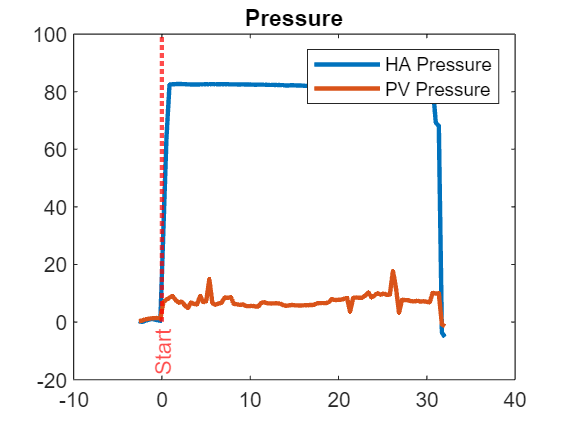

clf
plot(HA_pressure_time(1:PressureParse:end), HApressure(1:PressureParse:end), "LineWidth", 2)
hold on
plot(PV_pressure_time(1:PressureParse:end), PVpressure(1:PressureParse:end), "LineWidth", 2)
xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
hold on
title('Pressure')
legend('HA Pressure','PV Pressure')
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% remove -1 from CDI data

%NaN Variables
hapHNaN = find(table2array(CDI(:,2))==-1);
haPCO2NaN = find(table2array(CDI(:,3))==-1);
haPO2NaN = find(table2array(CDI(:,4))==-1);
bicarbNaN = find(table2array(CDI(:,5))==-1);
pvSO2NaN = find(table2array(CDI(:,15))==-1);
haSO2NaN = find(table2array(CDI(:,6))==-1);
pvpHNaN = find(table2array(CDI(:,11))==-1);
pvPCO2NaN = find(table2array(CDI(:,12))==-1);
pvPO2NaN = find(table2array(CDI(:,13))==-1);
pvSO2NaN = find(table2array(CDI(:,15))==-1);
kNaN = find(table2array(CDI(:,9))==-1);
hctNaN = find(table2array(CDI(:,18))<0);
hgbNaN = find(table2array(CDI(:,19))<0);


%makes variable and new time array for each variable, since different variables have
%different lengths once -1s have been removed

%ha pH
hapH(hapHNaN) = [];
hapH_time = CDI_time;
hapH_time(hapHNaN) = [];

%pv pH
pvpH(pvpHNaN) = [];
pvpH_time = CDI_time;
pvpH_time(pvpHNaN) = [];

%ha PCO2
haPCO2(haPCO2NaN) = [];
haPCO2_time = CDI_time;
haPCO2_time(haPCO2NaN) = [];

%pv PCO2
pvPCO2(pvPCO2NaN) = [];
pvPCO2_time = CDI_time;
pvPCO2_time(pvPCO2NaN) = [];

%ha PO2
haPO2(haPO2NaN) = [];
haPO2_time = CDI_time;
haPO2_time(haPO2NaN) = [];

%pv PO2
pvPO2(pvPO2NaN) = [];
pvPO2_time = CDI_time;
pvPO2_time(pvPO2NaN) = [];

%ha SO2
haSO2(haSO2NaN) = [];
haSO2_time = CDI_time;
haSO2_time(haSO2NaN) = [];

%pv SO2
pvSO2(pvSO2NaN) = [];
pvSO2_time = CDI_time;
pvSO2_time(pvSO2NaN) = [];

%K
k(kNaN) = [];
k_time = CDI_time;
k_time(kNaN) = [];

% %hct
hct(hctNaN) = [];
hct_time = CDI_time;
hct_time(hctNaN) = [];

%hgb
hgb(hgbNaN) = [];
hgb_time = CDI_time;
hgb_time(hgbNaN) = [];

**Potassium: **marker of cell death during perfusion (lysis, hepatocyte death)

Important notes during run: first spike refers to putting the liver on, dialyzed off over time -- these are less reliable than our NOVA readings, so refer to that chart

% clf
% plot(k_time(1:100:end), k(1:100:end), "LineWidth", 2)
% xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
% title("Potassium")
% xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")


**Hemolysis**

Important notes during run: refer to nova excel but these are decently close; 

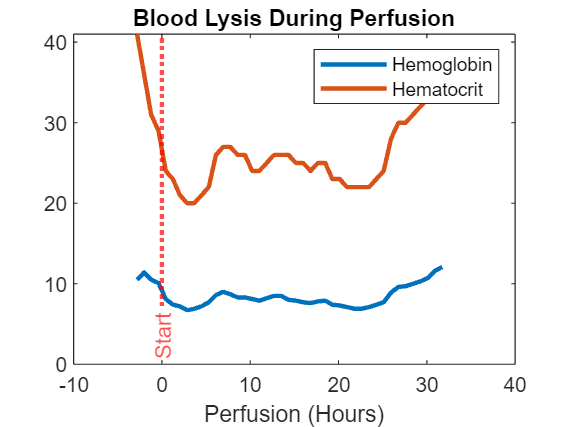

clf
plot(hgb_time(1:100:end), hgb(1:100:end), "LineWidth",2)
hold on
plot(hct_time(1:100:end), hct(1:100:end), "LineWidth",2)
xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
title("Blood Lysis During Perfusion")
legend("Hemoglobin", "Hematocrit")
xlabel("Perfusion (Hours)")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

**Oxygen Gradient Between HA and PV **

Important notes during run: drop in HA sat is because our oxygen tank was turned off randomly? 

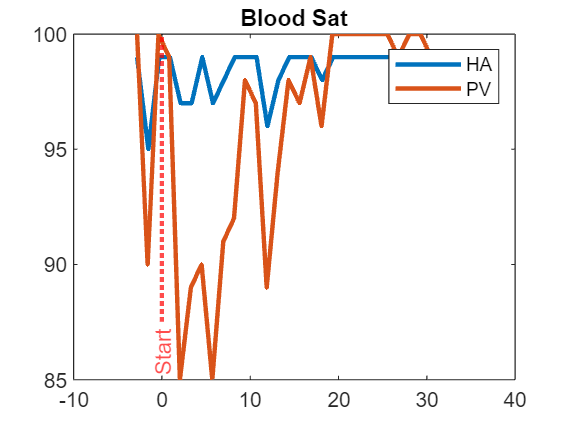

clf
plot(haSO2_time(1:150:end), haSO2(1:150:end), "LineWidth", 2)
hold on
plot(pvSO2_time(1:150:end), pvSO2(1:150:end), "LineWidth", 2)
xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
title("Blood Sat")
legend("HA", "PV")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

**pH**

Important notes during run: high PCO2 and low acidity as we added the liver because we realized we needed another liter of blood since we estimated the liver would take up a liter (it ended up taking 2.5 liters). In future runs, we definitely need to start out with an amount of blood relative to the liver size. 

% clf
% plot(hapH_time(1:CO2Parse:end), hapH(1:CO2Parse:end), "LineWidth", 2)
% hold on
% plot(pvpH_time(1:CO2Parse:end), pvpH(1:CO2Parse:end), "LineWidth", 2)
% xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
% legend('HA','PV')
% title('pH: CDI')
% if ~isempty(AnnotationsTime)
%    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
% end
% hold off


**Gas Control: How Gas Mixer Affects PO2**

Important notes during run: PV oxygenator broke around hour 8, used a CAPIOX one that seemed to work well enough, but it also broke so took it out around hour 15

% clf
% yyaxis("left")
% plot(haPO2_time(1:GasParse:end), haPO2(1:GasParse:end), "LineWidth",2)
% hold on
% title("Hepatic Artery PO2 Control")
% ylabel("mmHg")
% yyaxis("right")
% plot(HA_gas_time(1:GasParse:end), HAgas(1:GasParse:end), "LineWidth",2)
% ylabel("mL/min")
% xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
% legend("Hepatic Artery PO2", "Oxygen Flow")
% xlabel("Perfusion (Hours)")
% if ~isempty(AnnotationsTime)
%    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
% end
% hold off
% 
% clf
% yyaxis("left")
% plot(pvPO2_time(1:GasParse:end), pvPO2(1:GasParse:end), "LineWidth",2)
% hold on 
% title("Portal Vein PO2 Control")
% ylabel("mmHg")
% yyaxis("right")
% plot(PV_gas_time, PVgas, "LineWidth",2)
% ylabel("mL/min")
% ylim([0 300])
% xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
% legend("Portal Vein PO2", "Nitrogen Flow")
% xlabel("Perfusion (Hours)")
% if ~isempty(AnnotationsTime)
%    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
% end
% hold off

**PCO2**

Important notes during run: these stayed high the whole time which kept our blood acidic. 

% clf
% plot(pvPCO2_time(1:CO2Parse:end), pvPCO2(1:CO2Parse:end), "LineWidth", 2)
% hold on
% plot(haPCO2_time(1:CO2Parse:end), haPCO2(1:CO2Parse:end), "LineWidth", 2)
% xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
% legend('HA','PV')
% title('PCO2 (mmHg)')
% if ~isempty(AnnotationsTime)
%    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
% end
% hold off

**Hemodynamics for Hepatic Artery**

Important notes during run: 

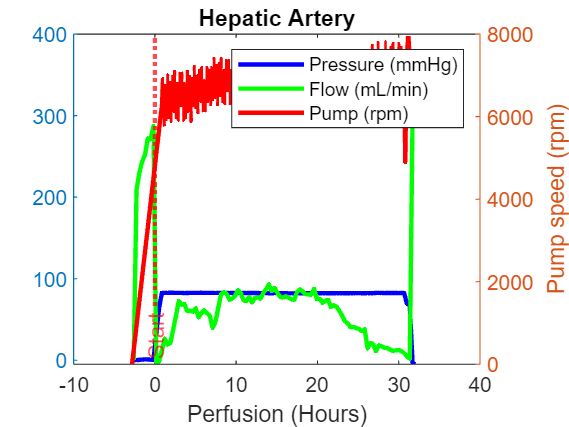

clf
yyaxis left
plot(HA_pressure_time(1:PressureParse:end), HApressure(1:PressureParse:end), "LineWidth",2, "LineStyle","-", "Color","blue");
hold on
plot(HA_flow_time(1:FlowParse:end), HAflow(1:FlowParse:end), "LineWidth",2, "LineStyle","-", "Color","green")
xlabel("Perfusion (Hours)")
ylim([-5,400])
yyaxis right
plot(HA_pump_time(1:FlowParse:end), HApump(1:FlowParse:end), "LineWidth",2, "LineStyle","-", "Color","red")
title("Hepatic Artery")
xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
legend("Pressure (mmHg)", "Flow (mL/min)", "Pump (rpm)")
ylabel("Pump speed (rpm)")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

**Hemodynamics for Portal Vein**

Important notes during run: flow drop at 36 hours -- probably from adding new blood, but liver did not recover -- eventually led to termination

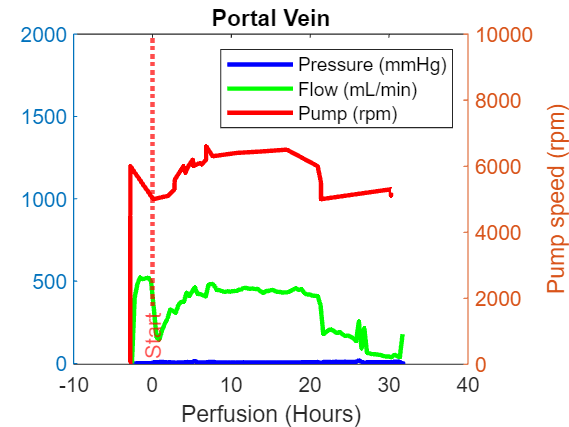

clf
yyaxis left
plot(PV_pressure_time(1:PressureParse:end), PVpressure(1:PressureParse:end), "LineWidth",2, "LineStyle","-", "Color","blue");
hold on
plot(PV_flow_time(1:FlowParse:end), PVflow(1:FlowParse:end), "LineWidth",2, "LineStyle","-", "Color","green")
xlabel("Perfusion (Hours)")
ylim([-5,2000])
yyaxis right
plot(PV_pump_time, PVpump, "LineWidth",2, "LineStyle","-", "Color","red")
title("Portal Vein")
xline(liver_start_time,":","Start", "LabelVerticalAlignment","bottom", "LabelHorizontalAlignment","center", "LineWidth",2,"Color","Red")
legend("Pressure (mmHg)", "Flow (mL/min)", "Pump (rpm)")
ylabel("Pump speed (rpm)")
ylim([0,10000])
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

# **(NOVA) **Post-Run Data Analysis: Perfusitech Ex-R

clf

% Raw Data Import
PVdataRaw = readtable("PortalVeinLabs.csv","VariableNamingRule","preserve");

HAdataRaw = readtable("HepaticArteryLabs.csv","VariableNamingRule","preserve");

IVCdataRaw = readtable("IVCLabs.csv","VariableNamingRule","preserve");

BiledataRaw = readmatrix("BileLabs.csv"); % Read matrix used for Bile data due to CSV reading difficulties



PVdataRaw = table2array(PVdataRaw(:,2:16));
HAdataRaw = table2array(HAdataRaw(:,2:16));
IVCdataRaw = table2array(IVCdataRaw(:,2:16));
BiledataRaw = BiledataRaw(:,3:6);


% 2 - time, 3 - pH, 4 - pCO2, 
% 5 - pO2, 6 - sO2, 7 - Hct,
% 8 - Hgb, 9 - Na, 10 - K, 
% 11 - Cl , 12 - Ca, 13 - Glucose, 
% 14 - Lactate, 15 - TCO2, 16 - HCO3

% Extraneous Truncation
experiment_start = 0;
experiment_end = 50;
PVtimeRaw = PVdataRaw(:,1);
HAtimeRaw = HAdataRaw(:,1);
IVCtimeRaw = IVCdataRaw(:,1);
BiletimeRaw = BiledataRaw(:,1);

PVtruncation_mask = (PVtimeRaw < experiment_start) | (PVtimeRaw > experiment_end);
HAtruncation_mask = (HAtimeRaw < experiment_start) | (HAtimeRaw > experiment_end);
IVCtruncation_mask = (IVCtimeRaw < experiment_start) | (IVCtimeRaw > experiment_end);
Biletruncation_mask = (BiletimeRaw < experiment_start) | (BiletimeRaw > experiment_end);

PVtimeRaw = PVtimeRaw(~PVtruncation_mask);
HAtimeRaw = HAtimeRaw(~HAtruncation_mask);
IVCtimeRaw = IVCtimeRaw(~IVCtruncation_mask);
BiletimeRaw = BiletimeRaw(~Biletruncation_mask);

% NaN Truncation
PVfinalArray = [];
for i = 2:15
    temp_dep = PVdataRaw(:,i);
    temp_dep = temp_dep(~PVtruncation_mask);
    temp_time = PVtimeRaw;
    nan_mask = isnan(temp_dep);
    temp_dep = temp_dep(~nan_mask);
    temp_time = temp_time(~nan_mask);
    temp = {[temp_time temp_dep]};
    PVfinalArray = [PVfinalArray temp];
end

HAfinalArray = [];
for i = 2:15
    temp_dep = HAdataRaw(:,i);
    temp_dep = temp_dep(~HAtruncation_mask);
    temp_time = HAtimeRaw;
    nan_mask = isnan(temp_dep);
    temp_dep = temp_dep(~nan_mask);
    temp_time = temp_time(~nan_mask);
    temp = {[temp_time temp_dep]};
    HAfinalArray = [HAfinalArray temp];
end

IVCfinalArray = [];
for i = 2:15
    temp_dep = IVCdataRaw(:,i);
    temp_dep = temp_dep(~IVCtruncation_mask);
    temp_time = IVCtimeRaw;
    nan_mask = isnan(temp_dep);
    temp_dep = temp_dep(~nan_mask);
    temp_time = temp_time(~nan_mask);
    temp = {[temp_time temp_dep]};
    IVCfinalArray = [IVCfinalArray temp];
end

finalArray = [PVfinalArray;HAfinalArray;IVCfinalArray];

BilefinalArray = [];
for i = 2:4
    temp_dep = BiledataRaw(:,i);
    temp_dep = temp_dep(~Biletruncation_mask);
    temp_time = BiletimeRaw;
    nan_mask = isnan(temp_dep);
    temp_dep = temp_dep(~nan_mask);
    temp_time = temp_time(~nan_mask);
    temp = {[temp_time temp_dep]};
    BilefinalArray = [BilefinalArray temp];
end

#### pH vs. Time Plotting

Important notes during run: 

PVpH = cell2mat(finalArray(1,1));
HApH = cell2mat(finalArray(2,1));
IVCpH = cell2mat(finalArray(3,1));
tiledlayout(3,1)
nexttile

plot(PVpH(:,1),PVpH(:,2),"Color","#C8533A","LineWidth",2)
ylabel("pH")
xlabel("Time [Hours]")
hold on
plot(HApH(:,1),HApH(:,2),"Color", "#3467C1", "LineWidth", 2)
plot(IVCpH(:,1),IVCpH(:,2),"Color", "#74B16A", "LineWidth", 2)
legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
yline(7.25,"LineWidth",1.5,"Color", "#702963", "LineStyle","--", "HandleVisibility","off")
yline(7.45,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

#### pCO2 vs. Time Plotting

Important notes during run: 

PVpCO2 = cell2mat(finalArray(1,2));
HApCO2 = cell2mat(finalArray(2,2));
IVCpCO2 = cell2mat(finalArray(3,2));

nexttile

plot(PVpCO2(:,1),PVpCO2(:,2),"Color","#C8533A","LineWidth",2)
ylabel("pCO2 [mmHg]")
xlabel("Time [Hours]")
hold on
plot(HApCO2(:,1),HApCO2(:,2),"Color", "#3467C1", "LineWidth", 2)
plot(IVCpCO2(:,1),IVCpCO2(:,2),"Color", "#74B16A", "LineWidth", 2)
legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
yline(40,"LineWidth",1.5,"Color", "#702963", "LineStyle","--", "HandleVisibility","off")
yline(25,"LineWidth",1.5,"Color", "#702963", "LineStyle","--", "HandleVisibility","off")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

#### HCO3 vs. Time Plotting

Important notes during run: 

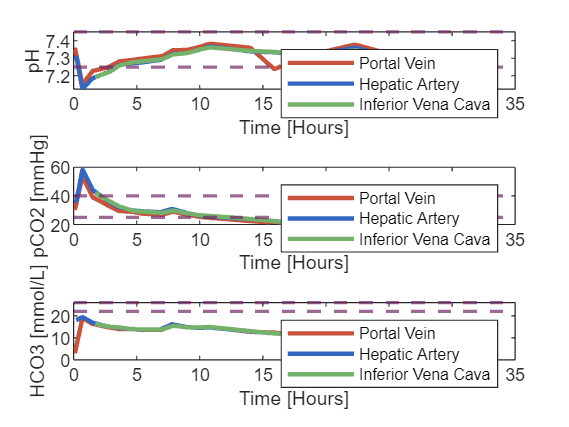

PVHCO3 = cell2mat(finalArray(1,14));
HAHCO3 = cell2mat(finalArray(2,14));
IVCHCO3 = cell2mat(finalArray(3,14));

nexttile

plot(PVHCO3(:,1),PVHCO3(:,2),"Color","#C8533A","LineWidth",2)
ylabel("HCO3 [mmol/L]")
xlabel("Time [Hours]")
hold on
plot(HAHCO3(:,1),HAHCO3(:,2),"Color", "#3467C1", "LineWidth", 2)
plot(IVCHCO3(:,1),IVCHCO3(:,2),"Color", "#74B16A", "LineWidth", 2)
legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
yline(22,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
yline(26,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

clf

#### pO2 vs. Time Plotting

Important notes during run: 

tiledlayout(2,1)
PVpO2 = cell2mat(finalArray(1,3));
HApO2 = cell2mat(finalArray(2,3));
IVCpO2 = cell2mat(finalArray(3,3));

nexttile 

plot(PVpO2(:,1),PVpO2(:,2),"Color","#C8533A","LineWidth",2)
ylabel("pO2 [mmHg]")
xlabel("Time [Hours]")
hold on
plot(HApO2(:,1),HApO2(:,2),"Color", "#3467C1", "LineWidth", 2)
plot(IVCpO2(:,1),IVCpO2(:,2),"Color", "#74B16A", "LineWidth", 2)
legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
yline(95,"LineWidth",1.5,"Color", "#3467C1", "LineStyle","--", "HandleVisibility","off")
yline(150,"LineWidth",1.5,"Color", "#3467C1", "LineStyle","--", "HandleVisibility","off")
yline(85,"LineWidth",1.5,"Color", "#C8533A", "LineStyle","--", "HandleVisibility","off")
yline(70,"LineWidth",1.5,"Color", "#C8533A", "LineStyle","--", "HandleVisibility","off")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

#### sO2 vs. Time Plotting

Important notes during run: 

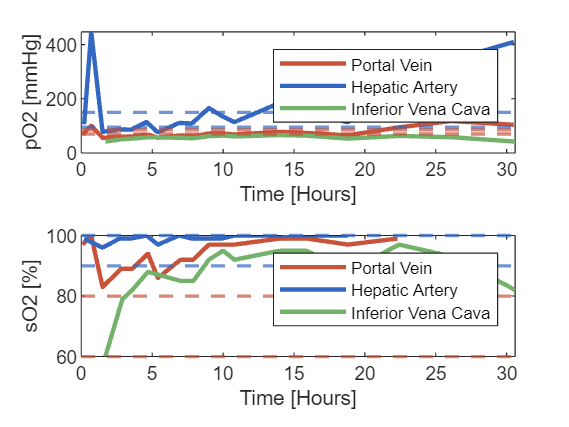

PVsO2 = cell2mat(finalArray(1,4));
HAsO2 = cell2mat(finalArray(2,4));
IVCsO2 = cell2mat(finalArray(3,4));

nexttile

plot(PVsO2(:,1),PVsO2(:,2),"Color","#C8533A","LineWidth",2)
ylabel("sO2 [%]")
xlabel("Time [Hours]")
hold on
plot(HAsO2(:,1),HAsO2(:,2),"Color", "#3467C1", "LineWidth", 2)
plot(IVCsO2(:,1),IVCsO2(:,2),"Color", "#74B16A", "LineWidth", 2)
legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
yline(90,"LineWidth",1.5,"Color", "#3467C1", "LineStyle","--", "HandleVisibility","off")
yline(100,"LineWidth",1.5,"Color", "#3467C1", "LineStyle","--", "HandleVisibility","off")
yline(80,"LineWidth",1.5,"Color", "#C8533A", "LineStyle","--", "HandleVisibility","off")
yline(60,"LineWidth",1.5,"Color", "#C8533A", "LineStyle","--", "HandleVisibility","off")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

#### Hct vs. Time Plotting

Important notes during run: 

clf

PVHct = cell2mat(finalArray(1,5));
HAHct = cell2mat(finalArray(2,5));
IVCHct = cell2mat(finalArray(3,5));
tiledlayout(3,1)
nexttile

plot(PVHct(:,1),PVHct(:,2),"Color","#C8533A","LineWidth",2)
ylabel("Hct [%]")
xlabel("Time [Hours]")
hold on
plot(HAHct(:,1),HAHct(:,2),"Color", "#3467C1", "LineWidth", 2)
plot(IVCHct(:,1),IVCHct(:,2),"Color", "#74B16A", "LineWidth", 2)
legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
yline(25,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

#### Hgb vs. Time Plotting

Important notes during run: 

PVHgb = cell2mat(finalArray(1,6));
HAHgb = cell2mat(finalArray(2,6));
IVCHgb = cell2mat(finalArray(3,6));

nexttile 

plot(PVHgb(:,1),PVHgb(:,2),"Color","#C8533A","LineWidth",2)
ylabel("Hgb [g/dL]")
xlabel("Time [Hours]")
hold on
plot(HAHgb(:,1),HAHgb(:,2),"Color", "#3467C1", "LineWidth", 2)
plot(IVCHgb(:,1),IVCHgb(:,2),"Color", "#74B16A", "LineWidth", 2)
legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
yline(8,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

#### Na vs. Time Plotting

Important notes during run: 

% PVNa = cell2mat(finalArray(1,7));
% HANa = cell2mat(finalArray(2,7));
% IVCNa = cell2mat(finalArray(3,7));
% plot(PVNa(:,1),PVNa(:,2),"Color","#C8533A","LineWidth",2)
% ylabel("Na [mmol/L]")
% xlabel("Time [Hours]")
% hold on
% plot(HANa(:,1),HANa(:,2),"Color", "#3467C1", "LineWidth", 2)
% plot(IVCNa(:,1),IVCNa(:,2),"Color", "#74B16A", "LineWidth", 2)
% legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
% yline(130,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
% yline(150,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
% if ~isempty(AnnotationsTime)
%    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
% end
% hold off

#### K vs. Time Plotting

Important notes during run: 

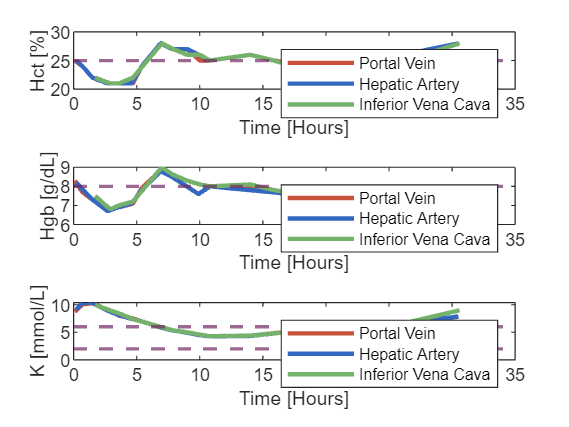

PVK = cell2mat(finalArray(1,8));
HAK = cell2mat(finalArray(2,8));
IVCK = cell2mat(finalArray(3,8));

nexttile 

plot(PVK(:,1),PVK(:,2),"Color","#C8533A","LineWidth",2)
ylabel("K [mmol/L]")
xlabel("Time [Hours]")
hold on
plot(HAK(:,1),HAK(:,2),"Color", "#3467C1", "LineWidth", 2)
plot(IVCK(:,1),IVCK(:,2),"Color", "#74B16A", "LineWidth", 2)
legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
yline(2,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
yline(6,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

#### Cl vs. Time Plotting

Important notes during run: 

clf 

% PVCl = cell2mat(finalArray(1,9));
% HACl = cell2mat(finalArray(2,9));
% IVCCl = cell2mat(finalArray(3,9));
% plot(PVCl(:,1),PVCl(:,2),"Color","#C8533A","LineWidth",2)
% ylabel("Cl [mmol/L]")
% xlabel("Time [Hours]")
% hold on
% plot(HACl(:,1),HACl(:,2),"Color", "#3467C1", "LineWidth", 2)
% plot(IVCCl(:,1),IVCCl(:,2),"Color", "#74B16A", "LineWidth", 2)
% legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
% yline(97,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
% yline(107,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
% if ~isempty(AnnotationsTime)
%    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
% end
% hold off

#### Ca vs. Time Plotting

Important notes during run: 

% PVCa = cell2mat(finalArray(1,10));
% HACa = cell2mat(finalArray(2,10));
% IVCCa = cell2mat(finalArray(3,10));
% plot(PVCa(:,1),PVCa(:,2),"Color","#C8533A","LineWidth",2)
% ylabel("Ca [mmol/L]")
% xlabel("Time [Hours]")
% hold on
% plot(HACa(:,1),HACa(:,2),"Color", "#3467C1", "LineWidth", 2)
% plot(IVCCa(:,1),IVCCa(:,2),"Color", "#74B16A", "LineWidth", 2)
% legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
% yline(1.1,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
% yline(0.9,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
% if ~isempty(AnnotationsTime)
%    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
% end
% hold off

#### Glucose vs. Time Plotting

Important notes during run: 

tiledlayout(2,1)
PVGlucose = cell2mat(finalArray(1,11));
HAGlucose = cell2mat(finalArray(2,11));
IVCGlucose = cell2mat(finalArray(3,11));
nexttile
plot(PVGlucose(:,1),PVGlucose(:,2),"Color","#C8533A","LineWidth",2)
ylabel("Glucose [mg/dL]")
xlabel("Time [Hours]")
hold on
plot(HAGlucose(:,1),HAGlucose(:,2),"Color", "#3467C1", "LineWidth", 2)
plot(IVCGlucose(:,1),IVCGlucose(:,2),"Color", "#74B16A", "LineWidth", 2)
legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
yline(80,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
yline(180,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

#### Lactate vs. Time Plotting

Important notes during run: 

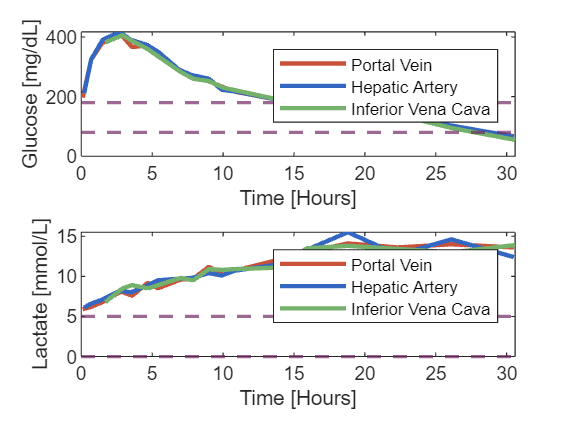

PVLactate = cell2mat(finalArray(1,12));
HALactate = cell2mat(finalArray(2,12));
IVCLactate = cell2mat(finalArray(3,12));
nexttile
plot(PVLactate(:,1),PVLactate(:,2),"Color","#C8533A","LineWidth",2)
ylabel("Lactate [mmol/L]")
xlabel("Time [Hours]")
hold on
plot(HALactate(:,1),HALactate(:,2),"Color", "#3467C1", "LineWidth", 2)
plot(IVCLactate(:,1),IVCLactate(:,2),"Color", "#74B16A", "LineWidth", 2)
legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
yline(0,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
yline(5,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end
hold off

#### TCO2 vs. Time Plotting

Important notes during run: 

% PVTCO2 = cell2mat(finalArray(1,13));
% HATCO2 = cell2mat(finalArray(2,13));
% IVCTCO2 = cell2mat(finalArray(3,13));
% plot(PVTCO2(:,1),PVTCO2(:,2),"Color","#C8533A","LineWidth",2)
% ylabel("TCO2 [mmol/L]")
% xlabel("Time [Hours]")
% hold on
% plot(HATCO2(:,1),HATCO2(:,2),"Color", "#3467C1", "LineWidth", 2)
% plot(IVCTCO2(:,1),IVCTCO2(:,2),"Color", "#74B16A", "LineWidth", 2)
% legend("Portal Vein", "Hepatic Artery", "Inferior Vena Cava")
% yline(23,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
% yline(29,"LineWidth",1.5,"Color", "#702963", "LineStyle","--","HandleVisibility","off")
% if ~isempty(AnnotationsTime)
%    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
% end
% hold off

#### Bile Rate vs. Time Plotting

Important notes during run: 

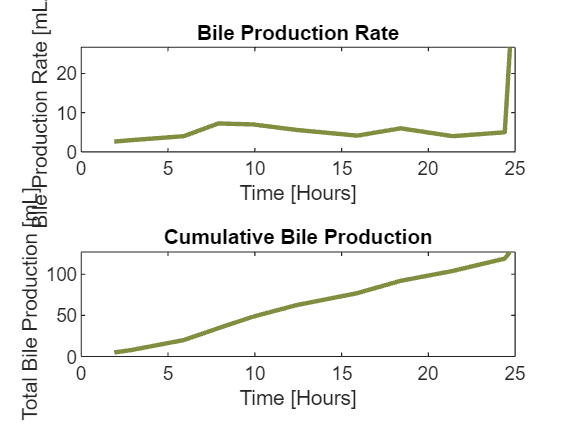

tiledlayout(2,1)
nexttile
BileRate = cell2mat(BilefinalArray(3));
plot(BileRate(:,1),BileRate(:,2),"Color", "#7F8E3F", "LineWidth", 2)
ylabel("Bile Production Rate [mL/hr]")
xlabel("Time [Hours]")
title("Bile Production Rate")
if ~isempty(AnnotationsTime)
    xline(AnnotationsTime,':',Alphabet,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','Center',"LineWidth",2,'LabelOrientation','Horizontal',"HandleVisibility","off")
end


Bile = cell2mat(BilefinalArray(2));
BileTotal = Bile(:,2);
BileTotals = zeros(length(BileTotal));

for i = 1:length(BileTotal)
    BileTotals(i) = sum(BileTotal(1:i));
end
nexttile
plot(BileRate(:,1),BileTotals(:,1),"Color", "#7F8E3F", "LineWidth", 2)
ylabel("Total Bile Production [mL]")
xlabel("Time [Hours]")
title("Cumulative Bile Production")